# Webcam Computer Vision Functions

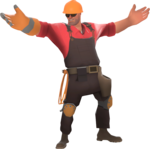

Eliyahu Suskind and Mahderekal, 2/24/2023, Revision 1

clc       % clear command window
clear     % clear MATLAB workspace
imaqreset % clear images from memory

### Set Up Control System

% Detect and create webcam object
camList = webcamlist
roboCam = webcam(2)
setUpWebcam(roboCam);

% Test camera, wait for user confirm
preview(roboCam);
CamTest = input( ...
    "Press enter when ready to rumble.","s" ...
    );
clc;
closePreview(roboCam);

% Test IMTool, wait for user confirm
img = snapshot(roboCam);
imtool(img);
CamTest = input( ...
    "Experiment with IMTool, then hit enter when ready","s" ...
    );
clc;

% Create free floating figure for livescript update help
camWindow = figure( ...
    "name","Robot USB Camera","NumberTitle","off","Visible","on" ...
    );
figure(camWindow)
imshow(img,"Border","tight")

% Configure loop to test n data points
nTest = input( ...
    "DO NOT CLOSE FIGURE. Enter small number of camera tests, and hit enter when ready: " ...
    );
clc;
r= rateControl(0.1);
reset(r);

### Run Control Loop

controlFlag = 1;

while (controlFlag < nTest +1)

    [centroids, targetArea, testPixels] = SENSE(roboCam, camWindow)

    CamTest = input("Press Enter to advance tests.","s");
    clc;

    waitfor(r);
    controlFlag = controlFlag + 1;
end

### Mission data processing

CamTest = input("Press Enter to move to live video.","s");
backgroundPic = snapshot(roboCam);
frames = 2000;
for i = 1:frames

    
end

### Clean and Shutdown

End program by clearning webcam object and command window.

clc;
clear roboCam;
disp("Tests Done, Cleaning Up.")
beep

### Sense Functions

function [centroids, targetArea, testPixels] = SENSE(roboCam, myFigure)

% Create filtered webcam image, prompt user input
robotImage = snapshot(roboCam);
[targetMask, yellowMasked] = yellowMask(robotImage);
figure(myFigure)
imshow(targetMask)
CamTest = input("Ensure filter is OK, then hit enter.","s");
clc;

% Fill noise, prompt user input, if bad re-do woth new fill value
fillFlag = 1;
testPixels = 30;
while fillFlag 
cleanImage = bwareaopen(targetMask,testPixels);
figure(myFigure)
imshow(cleanImage)
testPixels = input(...
    "If filter is OK, hit enter. Else enter size in pixels of noise: " ...
    );
clc;
if isempty(testPixels)
    break
end
end

% Find centroid, prompt user input
targetCenter = regionprops(cleanImage, 'centroid');
centroids = cat(1, targetCenter.Centroid);
figure(myFigure)
imshow(robotImage)
hold on
plot(centroids(:,1), centroids(:,2), 'b*')
text(centroids(:,1), centroids(:,2), 'Centroid');
hold off
CamTest = input('Check out target center and hit enter.', 's');
clc;

% Find object area(s), prompt user input
targetArea = regionprops(cleanImage, 'area');
area = targetArea.Area;
centroids = cat(1, targetCenter.Centroid);
figure(myFigure) 
imshow(robotImage)
hold on
plot(centroids(:,1), centroids(:,2), 'b*')
text(centroids(:,1), (centroids(:,2)+10), num2str(area));
hold off
CamTest = input('Check out target area and hit enter.', 's');
clc;

end

function cleanImage = noImSense(roboCam, myFigure, testPixels)
% Sense without IMShows or Centroid/Area Finding for Live Cam

% Create filtered webcam image, prompt user input
robotImage = snapshot(roboCam);
[targetMask, yellowMasked] = yellowMask(robotImage);
figure(myFigure)
clc;

% Fill noise in filtered image
cleanImage = bwareaopen(targetMask,testPixels);
figure(myFigure)
clc;

end

function setUpWebcam(roboCam)
% Sense function to set up roboCam balance mode
% Input: roboCam is webcam object to be set up

    roboCam.WhiteBalanceMode = "manual";
    roboCam.Brightness = 100;

end